CRO_st.name='CRO'; 
CRO_st.lat=32.941;
CRO_st.lon=-79.6572;
CRO_st.alt=4;

CRO_rd=read_betsy('capero_head',CRO_st.name);

datevec(CRO_rd.Time(1))

ans =         2004           1           2           0           0           0

datevec(CRO_rd.Time(end))

ans =         2013           1           1           0           0           0

prctile(CRO_rd.U_S11,[5, 50, 95])

ans =    58.5980   85.0400   96.8935

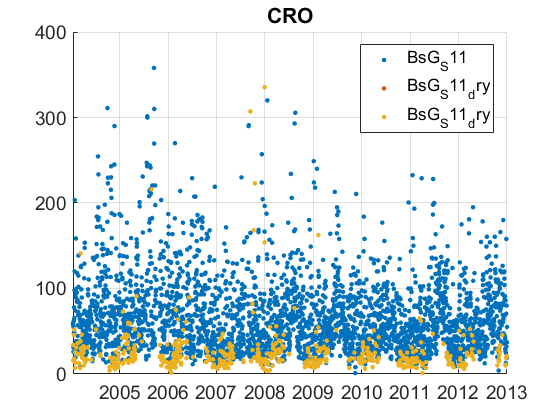

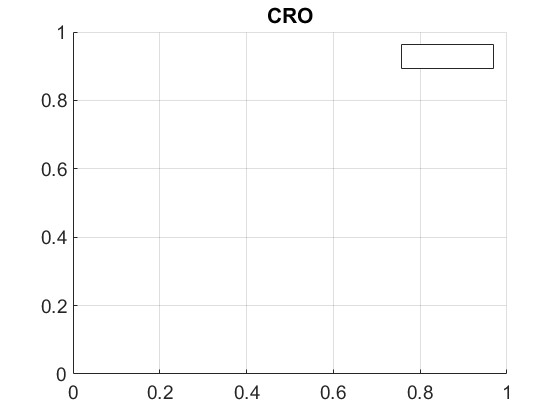

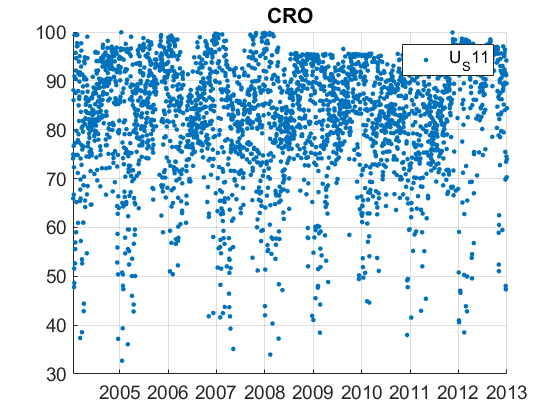

plotFigControl(CRO_rd,CRO_st.name);

% 1 size cut, since 2000
% sc: ok, clear seasonal cycle, max in summer, some negatives

% lambdaSC=[450;550;700]*ones(1,4); % lambdaAE3=[467;530;660]*ones(1,4); % lambdaAE7=[370 470 520 590 660 880 950]; % CRO_cal=compute_exp_SSA(CRO_rd,lambdaSC, lambdaAE3); % plotFigControl_cal(CRO_cal, CRO_st.name);

%Questions:
%problems:
% station parameters


CRO_tr=CRO_rd;
CRO_tr.y=year(CRO_tr.Time);
% begin at the beginning of a year:2004
%end year: 2013
P=timerange('2004-01-01','2013-01-01');
CRO_tr=CRO_tr(P,:);

names=fieldnames(CRO_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_"]) | endsWith(names,'T');
N=names(c);
for i=1:length(N)
    CRO_tr.(N{i})=[];
end
% dry: extremely low data data coverage, nothing in summer
%otherwise seems ok

% too short to compute trend